# Hypothesis Testing: Argus II retinal prosthesis 

Sam Coleman

### The Question 

We are primarily interested in understanding if the Argus II retinal prosthesis was effective in improving the subject's vision. The mean of the magnitude of difference between the target and the location of where the participant touched the screen. We want to see if the distance between where the participiant touched and the center is smaller with the system on?

Each participant has the mean of 40 trials of the value for when the system is on and when the system is off. The data is continuous.

### Determine your null hypothesis, alternative hypothesis, alpha value

**Null Hypothesis (H0)**: Argus II has no effect on people's vision. If the null hypothesis were true, there would be no change in distance for partiipaints. distanceOn - distanceOff = 0

**Alternative hypothesis**: Argus II had an effect on people's vision (the mean of the magnitude of difference between the target and where the participant touched the screen is different for system on and system off). DistanceOn - DistanceOff != 0

**Alpha value**: .05 

### Conduct your experiment and collect your data (Load Data).

data = readtable("argusData.csv") %import data

data = 29×3 table
    Participant    SystemOn    SystemOff
    ___________    ________    _________

       {'A'}         128          372   
       {'B'}         115          319   
       {'C'}         177          324   
       {'D'}         106          343   
       {'E'}         121          385   
       {'F'}         201          382   
       {'G'}         178          300   
       {'H'}         190          181   
       {'I'}         122          347   
       {'J'}         120          386   
       {'K'}         112          209   
       {'L'}         211           -1   
       {'M'}         103          404   
       {'N'}         102          536   
       {'O'}         199          327   
       {'P'}         237          312   


### Organize and clean the data

#### Understanding The Data

Participants are represented by Strings 'A' to 'AC'. There is a mean of 40 trials for both the system on and system off for each participant. 

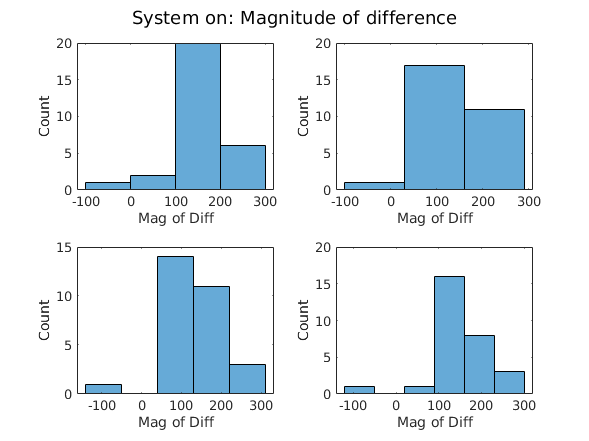

%Get an understanding of the distrubution: System On
figure();
sgtitle("System on: Magnitude of difference")
subplot(2,2,1)
histogram(data.SystemOn)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,2)
histogram(data.SystemOn, 3)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,3)
histogram(data.SystemOn, 5)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,4)
histogram(data.SystemOn, 6)
xlabel("Mag of Diff"); ylabel("Count");

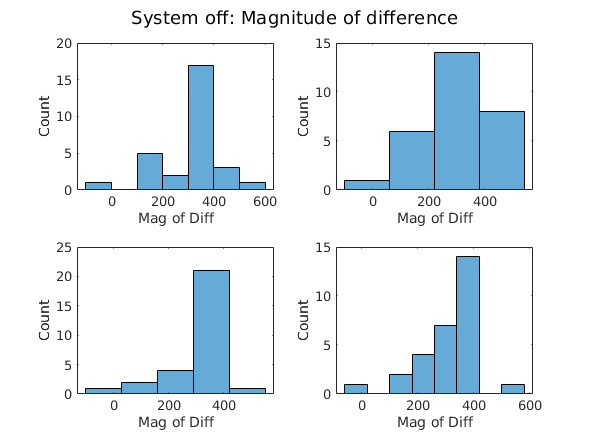

%Get an understanding of the distrubutionL System Off
figure();
sgtitle("System off: Magnitude of difference")
subplot(2,2,1)
histogram(data.SystemOff)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,2)
histogram(data.SystemOff,4)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,3)
histogram(data.SystemOff, 5)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,4)
histogram(data.SystemOff, 8)
xlabel("Mag of Diff"); ylabel("Count");

Looking at the histograms, we see there are negative values. This is not expected as the values are "the mean of the magnitude of difference." Below, I am looking closer into the negative values (based on the data I would expect everything to be >=0 but that is not the case). These values are not expected so they will be considered outliers, and not used in the testing.

#### Investiage (and Remove) Outliers

%see (the number of and values of) negative data in both SystemOn and
%SystemOff
data(data.SystemOn < 0, :)

ans = 1×3 table
    Participant    SystemOn    SystemOff
    ___________    ________    _________

       {'X'}         -99          136   


data(data.SystemOff < 0, :)

ans = 1×3 table
    Participant    SystemOn    SystemOff
    ___________    ________    _________

       {'L'}         211          -1    


Looking at the tables, we see there is one value for system on and one value for system off that is negative. As such, we will remove this data. Note, we remove the whole line of data (all data for that participant) since it is a paired experiment. 

%Remove outliers
data(data.SystemOff<0,:) = [];
data(data.SystemOn<0,:) = [];

%look at the summary of the data
summary(data)

Variables:

    Participant: 27×1 cell array of character vectors

    SystemOn: 27×1 double

        Values:

            Min          72   
            Median      128   
            Max         268   

    SystemOff: 27×1 double

        Values:

            Min         136   
            Median      343   
            Max         536   



### Reviewing Data

Now that we removed outliers, we will visualize our data again. This time, since we are interested in the difference of pixel distance for each participant between SystemOn and SystemOff, we will create a column in the table that holds this distance. This will also be what we plot on the histogram. Note: distance will be SystemOff - SystemOn so a positive value indicates an improvement when the system is on. 

data.Diff = data.SystemOff - data.SystemOn

data = 27×4 table
    Participant    SystemOn    SystemOff    Diff
    ___________    ________    _________    ____

       {'A'}         128          372       244 
       {'B'}         115          319       204 
       {'C'}         177          324       147 
       {'D'}         106          343       237 
       {'E'}         121          385       264 
       {'F'}         201          382       181 
       {'G'}         178          300       122 
       {'H'}         190          181        -9 
       {'I'}         122          347       225 
       {'J'}         120          386       266 
       {'K'}         112          209        97 
       {'M'}         103          404       301 
       {'N'}         102          536       434 
       {'O'}         199          327       128 
       {'P'}         237          312        75 
       {'Q'}

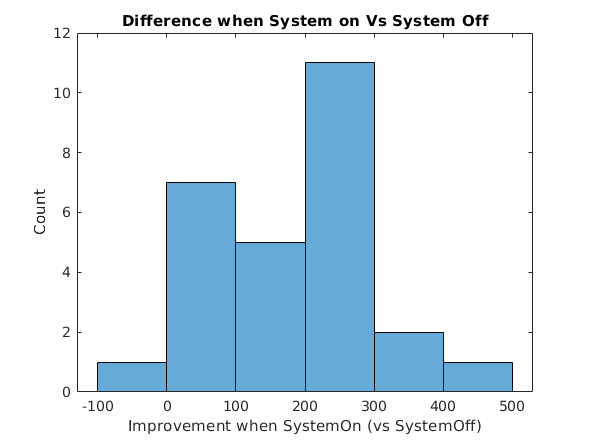

figure()
histogram(data.Diff)
xlabel("Improvement when SystemOn (vs SystemOff)")
ylabel("Count")
title("Difference when System on Vs System Off")

Looking at the histrogram, we it is a relatively normal distrubtion (this will be tested in the next section) and the SystemOn improves the accuracy for most participsants. 

### Determine what types of tests/measurements are appropriate to answer your question.

We have a set of data for each participant with using the Argus II and a set of data without using the Argus II. Therefore, I will use a **paired sample T test. **

Assumptions of a paired sample T test:

- The dependent variable must be continuous (interval/ratio). 

- The observations are independent of one another.

- The dependent variable should be approximately normally distributed.

- The dependent variable should not contain any outliers.

Test for normal distribution of the SystemOn vs SystemOff difference using lillietest:

[h, p] = lillietest(data.Diff)

h = 0

p = 0.1602

Based on the results from the lilietest (and from visually looking at the histograms), we see that the difference between SystemOn and SystemOff per subject is normally distributed. Thus, we will proceed with the paired sample T test. 

### Calculate appropriate measurements / tests

To reiterate our null hypothesis: H0 is that the Argus II has no effect on people's accuracy while performing this task (which would suggest it has no impact on people's vision). 

%Perform the paired sample T Test

%run paired t test
alpha = .05;
[H, P, CI, STATS] = ttest(data.SystemOff, data.SystemOn, "Alpha", alpha)

H = 1

P = 1.5414e-09

CI =   139.2520
  220.8221


STATS = struct with fields:
    tstat: 9.0737
       df: 26
       sd: 103.1002


#### Understanding the Output of Paired T Test

H = 1 means we *reject the null hypothesis* with our alpha value (currently .05). P is the p-value (the probability of getting our test statistic) or data more extreme given that our null hypothesis is true. As our p-value shows, the data is very unlikely if the null hypothesis is true, so we reject the null hypothesis. 

CI is the confidence interval, which in this case is a 95% confidence interval (1 - alpha). In this case, there is a 95% probability that any given confidence interval from a random sample will contain the true population mean.

The STATS gives some other information. As shown, the t-value is 9.0737.  A t-value of 0 indicates that the sample results exactly equal the null hypothesis. As the effect size (difference between the sample estimate and null hypothesis) increases, the absolute value of the t-value increases. This t-value, once again, tells us we should reject the null hypothesis. We have 26 degrees of freedom, which is the total number of observations (we got rid of those with a negative value) minus one (so 28 - 1 = 27). The sample standard deviation is 103.1002.

#### Effect Size

We will use the Cohen's d measure of effect size:

cohensd = mean(data.Diff) / STATS.sd 

cohensd = 1.7462

This effect size is very large. Note how .8 is often considered a "large" effect size, and our effect size is 1.7462. This value is the number of standard deviations we observe in our data.

### Graph to illustrate findings.

To give a better sense of the findings, below are several different graphs to illustrate the findings. 

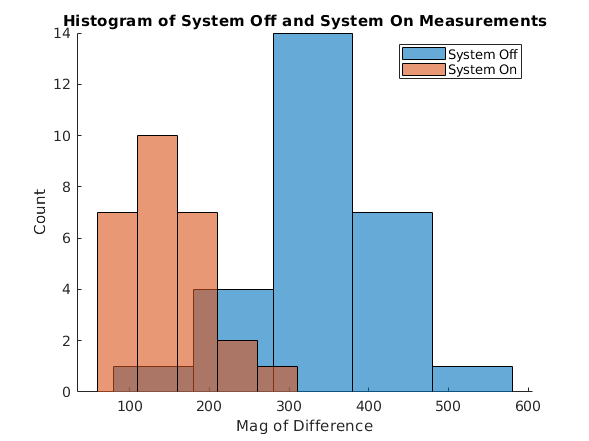

figure();
hold on;
histogram(data.SystemOff,5)
histogram(data.SystemOn,5)
title("Histogram of System Off and System On Measurements")
xlabel("Mag of Difference")
ylabel("Count")
legend("System Off", "System On")
hold off;

This histogram illustrates the differences (overall) in results between using the Argus II system and not using it. Below is a histogram showing of the diference per subject between SystemOn and SystemOff.

histogram(data.Diff)
xlabel("Improvement when SystemOn (vs SystemOff)")
ylabel("Count")
title("Difference when System on Vs System Off")

We can also visualize this with a boxplot for systemOn and systemOff.

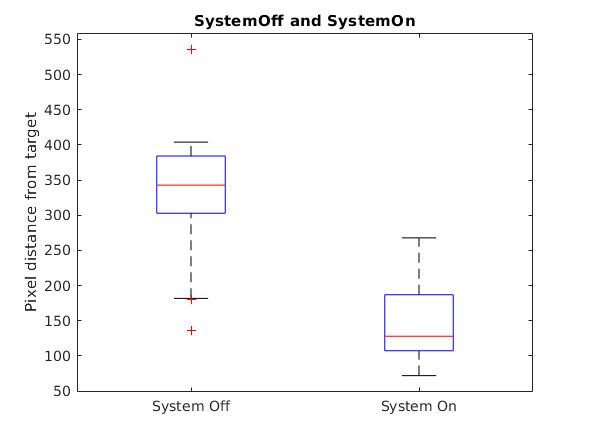

boxplot([data.SystemOff data.SystemOn])
title("SystemOff and SystemOn")
xticklabels(["System Off", "System On"])
ylabel("Pixel distance from target")

It is also helpful to look at a line graph where we can easily visualize the difference between SystemOff and SystemOn for each participant. In this graph, each participant is a line.

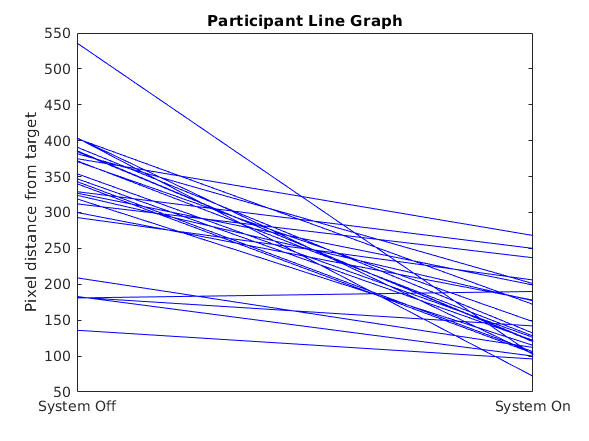

plot([data.SystemOff data.SystemOn]', 'b');
xticks([1 2])
xticklabels(["System Off", "System On"])
ylabel("Pixel distance from target")
title("Participant Line Graph")

### Summary of Useful Values

mean_improvement = mean(data.Diff)

mean_improvement = 180.0370

mean_sys_on = mean(data.SystemOn)

mean_sys_on = 149.1481

mean_sys_off = mean(data.SystemOff)

mean_sys_off = 329.1852

STATS

STATS = struct with fields:
    tstat: 9.0737
       df: 26
       sd: 103.1002


P

P = 1.5414e-09

cohensd

cohensd = 1.7462

### Summary of Findings

In this study, we compared the impact of using the Argus II Retinal Prosthesis on particpant's accuracy in determining the center of a white square stimulus. The less the magnitude of difference between the center of the stimulus and the participant's location touched, the more accurate they were. These samples were averaged over 40 trials and recorded for SystemOn and SystemOff for each participant. After eliminating outliers, this was analyzed for 27 participants. 

When the system was off, the mean distance between the square and location touched was 329.2 pixels, and it was 149.1 pixels when the System was on. The mean improvement was 180 pixels, with a standard deviation of 103.1 pixels. The Cohen's d measure of effect size of 1.7 was calculated, indicating a very large effect size. A paired t-test indicated a significant difference between SystemOff and SystemOn: t(27) = 9.07 with a p value of 2.7e-9. Based on these findings, the null hypothesis was rejected.